# Small Network With All Delays

## first, setup connctivity map

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
FigurePrePath = [CurrentFolder '/Figures/Demo043021/'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolder = [pwd '/Figures/Demo050721/'];
addpath(DataFolder)
OldDataFolder = [pwd '/Figures/Demo042421-1/'];
addpath(OldDataFolder)
% Make sure the old stuff is the same
load('NtWk_Archit.mat')
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2))*0.75; 
N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2))*0.75; %Plan A:Original
                                                                           %Plan B: Lower #ItoE and #I-to-I

% Now Make a small network s.t. the mean presynaptic neurons are equal to
% above
N_E = floor(3*N_IE); N_I = floor(1/3*N_E);
CS_EE = SmallNetworkGenerat(N_E,N_E,N_EE);
CS_IE = SmallNetworkGenerat(N_E,N_I,N_IE);
CS_EI = SmallNetworkGenerat(N_I,N_E,N_EI);
CS_II = SmallNetworkGenerat(N_I,N_I,N_II);

## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.500; rI_amb = 0.500;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80; % 80
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.6;  % was 1.52
                                 % Plan B: Increase S_EI to compensate
                                 % Plan C: 1.57; suboptimal drive
                                 % Plan D: 1.6; optimal drive
                                 % D': NE larger
                                 % Plan E': 1.78; optimal drive, reduce E firing rates to 23
                                 % Plan F'1-3: 1.6 but Reducing Drive
S_II = 0.120; S_IE = S_II*0.153;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 

Now: Delete L6 and amb, and transfer all to LGN.

S_ambU = S_EE; % there is only one Samb...So all align to E
rE_ambU = rE_amb*S_amb/S_ambU; rI_ambU = rI_amb*S_amb/S_ambU;
S_EL6U = S_Elgn; S_IL6U = S_Ilgn;
rE_L6U = rE_L6*S_EL6/S_EL6U;     rI_L6U = rI_L6*S_IL6/S_IL6U; %250hz for now

## Network Simulation

E_Ind = 1:N_E; I_Ind = 1:N_I;

%% Network Simulation
T = 3000; SimulationT = 1000; dt = 0.1;
% E-to-E delay time
T_EEDly = 0.9; N_EEDly = floor(T_EEDly/dt);
T_IEDly = 0.5; N_IEDly = floor(T_IEDly/dt);
T_EIDly = 0.5; N_EIDly = floor(T_EIDly/dt);
% Setup Results Recording
Fr_NW_BG      = zeros(2,1);
mV_NW_BG      = zeros(2,1);
%Fr_OneStep = zeros(2,EITestN,length(S_IEtest)); % one step MF estimation using network mV

N_EE = mean(sum(CS_EE,2)); N_EI = mean(sum(CS_EI,2));
N_IE = mean(sum(CS_IE,2)); N_II = mean(sum(CS_II,2));

% Create sliding windows
sampleT = 200;
Sliding = 100;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);

% The initial states
% load('IniTestSNW.mat');
% RefTimeE = EndState{1}; VE = EndState{2}; SpE = EndState{3}; GE_ampa_R = EndState{4}; GE_nmda_R = EndState{5}; GE_gaba_R = EndState{6};
%                                                              GE_ampa_D = EndState{7}; GE_nmda_D = EndState{8}; GE_gaba_D = EndState{9};
% RefTimeI = EndState{10};VI = EndState{11};SpI = EndState{12};GI_ampa_R = EndState{13};GI_nmda_R = EndState{14};GI_gaba_R = EndState{15};
%                                                              GI_ampa_D = EndState{16};GI_nmda_D = EndState{17};GI_gaba_D = EndState{18};
% if N_EEDly>=size(EndState{19},2)
% EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))]; 
% else
%     EEDlyRcd = EndState{19}(:,1:N_EEDly);
% end
% if N_IEDly>=size(EndState{20},2)
% IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))]; 
% else
%     IEDlyRcd = EndState{20}(:,1:N_IEDly);
% end
% EIDlyRcd = sparse(N_E,N_EIDly);
%E_SpHis= []; I_SpHis=[];
RefTimeE = zeros(N_E,1); VE = zeros(N_E,1); SpE =zeros(N_E,1); GE_ampa_R = zeros(N_E,1); GE_nmda_R = zeros(N_E,1); GE_gaba_R = zeros(N_E,1);
                                                             GE_ampa_D = zeros(N_E,1); GE_nmda_D = zeros(N_E,1); GE_gaba_D = zeros(N_E,1);
RefTimeI = zeros(N_I,1);VI = zeros(N_I,1);SpI = zeros(N_I,1);GI_ampa_R = zeros(N_I,1);GI_nmda_R = zeros(N_I,1);GI_gaba_R = zeros(N_I,1);
                                                             GI_ampa_D = zeros(N_I,1);GI_nmda_D = zeros(N_I,1);GI_gaba_D = zeros(N_I,1);

EEDlyRcd = sparse(N_E,N_EEDly);                                                             
IEDlyRcd = sparse(N_I,N_IEDly);
EIDlyRcd = sparse(N_E,N_EIDly);

E_Sp = []; I_Sp = [];
VE_T = []; VI_T = [];
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('FrEs',   zeros(size(Wins(:,1))), 'FrIs',   zeros(size(Wins(:,1))),...
    'mVEs',   zeros(size(Wins(:,1))), 'mVIs',   zeros(size(Wins(:,1))));
NWTrace.VEDist =  cell(size(Wins(:,1)));
NWTrace.VIDist =  cell(size(Wins(:,1)));
NWTrace.Wins = Wins;

tic
for TimeN = 1:floor(T/dt)
    [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
        oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
        oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
        oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
        oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
        V1NetworkUpdate_Ver3_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
        EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
        CS_EE,CS_EI,CS_IE,CS_II,...
        S_EE,S_EI,S_IE,S_II,...
        tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
        dt,p_EEFail,...
        gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
        gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
        S_ambU,lambda_E,lambda_I,rE_ambU,rI_ambU,...
        S_EL6U,S_IL6U,rE_L6U,rI_L6U); % L6 Parameters          % The lower/upper bounds for kick waiting time
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;
    
    % When reaching every 500ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>=400
        ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
            ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
            'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) ...
            ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
            'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
        
        fprintf(ParameterDisp)
        figure('Name','TestRaster');
        subplot 311
        hist(oVE,-0.3:0.02:1)
        title(['mVE = ' num2str(nanmean(VE_T))])
        %E_SpHis = [E_SpHis,sum(oSpE)];
        %axis([-0.4 1.1 0 6000])
        
        subplot 312
        hist(oVI,-0.3:0.02:1)
        title(['mVI = ' num2str(nanmean(VI_T))])
              
        %E_Ind = 10000:13000; I_Ind = 3300:4300;
        scatterE = find(ismember(E_Sp(:,1),E_Ind));
        scatterI = find(ismember(I_Sp(:,1),I_Ind));
        [~,E_Fire_Ind] = ismember(E_Sp(scatterE,1),E_Ind);
        [~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);
        
        WinSize = SimulationT;
        T_RateWindow = [TimeN*dt-WinSize TimeN*dt];
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        E_Rate = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        
        f_EnIOneStep = MeanFieldEst_BkGd_L6_OneStep(N_EE,N_EI,N_IE,N_II,...
                                                    S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                                    lambda_E,S_Elgn,rE_amb,S_amb,...
                                                    lambda_I,S_Ilgn,rI_amb,...
                                                    S_EL6,S_IL6,rE_L6,rI_L6,...
                                                    gL_E,gL_I,Ve,Vi,nanmean(VE_T),nanmean(VI_T));
        %
        subplot 313
        hold on
        scatter(E_Sp(scatterE,2),E_Fire_Ind,'r.')
        scatter(I_Sp(scatterI,2),I_Fire_Ind+max(E_Fire_Ind),'b.');
        title({['E-rate = ' num2str(E_Rate) ' est:' num2str(f_EnIOneStep(1))],['I-rate = ' num2str(I_Rate) ' est:' num2str(f_EnIOneStep(2))]})
        xlabel('Time (ms)')
        xlim(T_RateWindow)
        ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
        drawnow
        %pause
        %close(h)
        % end of 500ms plot
    end
    
    % every 20ms time window
    if mod(TimeN,sampleN) == 0 && TimeN >= floor(sampleT/dt)
        WinSize = NWTrace.Wins(SampleInd,2) - NWTrace.Wins(SampleInd,1);
        T_RateWindow = NWTrace.Wins(SampleInd,:);
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        
        NWTrace.FrEs(SampleInd) = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        NWTrace.FrIs(SampleInd) = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        NWTrace.mVEs(SampleInd) = nanmean(oVE(E_Ind));
        NWTrace.mVIs(SampleInd) = nanmean(oVI(I_Ind));
        
        NWTrace.VEDist{SampleInd} = oVE(E_Ind);
        NWTrace.VIDist{SampleInd} = oVI(I_Ind);
        
        SampleInd = SampleInd + 1;
        toc
    end
    
    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    VE_T = [VE_T;nanmean(oVE(E_Ind))];
    VI_T = [VI_T;nanmean(oVI(I_Ind))];
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end
toc

NWTrace.E_Sp = E_Sp; NWTrace.I_Sp = I_Sp;


% If blown up, discard other recordings...
if ~BlowUp
    Fr_NW_BG     = [E_Rate;I_Rate];
    mV_NW_BG     = [nanmean(VE_T),nanmean(VI_T)];
    %Fr_OneStep(:,S_EIInd,S_IEInd) = f_EnIOneStep;
end
% end of S_IE loop


## Now, with drive

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

- Kicks are all normalized to LGN sizes

DomInd = 1; % 1 for opt, 2 and 4 for sub-opt, 3 for worst;
%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
lgnE_DriveOrg = [60,50,42,50]; % The original Large LGN input before subtraction, per LGN cell, before normaliztion
lgn_spon = 20;
% Plan F'1-3: 1.6 but Reducing Drive
LGNChoice = 3; % 1 for high, original
               % 2 for medium, 2/3 after subtraction
               % 3 for small, 1/3 after subtraction
switch LGNChoice
    case 1
        lgnE_Drive =              lgnE_DriveOrg               *4/1e3;
    case 2
        lgnE_Drive = (lgn_spon + (lgnE_DriveOrg-lgn_spon)*2/3)*4/1e3;
    case 3
        lgnE_Drive = (lgn_spon + (lgnE_DriveOrg-lgn_spon)*1/3)*4/1e3;
end

lgnI_Drive = min(lgnE_Drive);
lambda_E_drive = lgnE_Drive(DomInd);
lambda_I_drive = lgnI_Drive;

L6E_Drive = [50 35 20 35]*50/1e3;
L6I_Drive = min(L6E_Drive);
rE_L6_DriveU = L6E_Drive(DomInd)*S_EL6/S_EL6U;
rI_L6_DriveU = 3*rE_L6_DriveU*S_IL6/S_IL6U;


% Making Poisson here/Reading
T = 50000; dt = 0.1;
TimeFrac = 0.05;
LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_ambU,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_ambU,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_DriveU*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_DriveU*(1-L6CurInp),T*TimeFrac,dt);

%   [A,~,Times] = find(eventsN);

Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

% E-to-E delay time
T_EEDly = .9; N_EEDly = floor(T_EEDly/dt);
T_IEDly = .5; N_IEDly = floor(T_IEDly/dt);
T_EIDly = .5; N_EIDly = floor(T_EIDly/dt);
% % The initial states
% InSs = load('Initials_L6.mat');
% RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
% GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
% RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
% GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
% EEDlyRcd = sparse(N_E,N_EEDly);

% The initial states, for more simulation 
load(['DriveWk_SNW_Sp_TestDly_EE0.9_IE0.5_NMDA80_45-50_Dp.mat'],'EndState');
%load('IniTestSNW_Dp.mat','EndState');
% RefTimeE = EndState{1}; VE = EndState{2}; SpE = EndState{3}; GE_ampa_R = EndState{4}; GE_nmda_R = EndState{5}; GE_gaba_R = EndState{6};
%                                                              GE_ampa_D = EndState{7}; GE_nmda_D = EndState{8}; GE_gaba_D = EndState{9};
% RefTimeI = EndState{10}; VI = EndState{11}; SpI = EndState{12}; GI_ampa_R = EndState{13}; GI_nmda_R = EndState{14}; GI_gaba_R = EndState{15};
%                                                                 GI_ampa_D = EndState{16}; GI_nmda_D = EndState{17}; GI_gaba_D = EndState{18};
% if N_EEDly>=size(EndState{19},2)
% EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))]; 
% else
%     EEDlyRcd = EndState{19}(:,1:N_EEDly);
% end
% if N_IEDly>=size(EndState{20},2)
% IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))]; 
% else
%     IEDlyRcd = EndState{20}(:,1:N_IEDly);
% end
% if N_EIDly>=size(EndState{21},2)
% EIDlyRcd = [EndState{21},zeros(N_E,N_EIDly-size(EndState{20},2))]; 
% else
%     EIDlyRcd = EndState{21}(:,1:N_EIDly);
% end
%EIDlyRcd = repmat(CS_EI*SpI,1,N_EIDly);
[RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
          RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
          EEDlyRcd, IEDlyRcd, EIDlyRcd]...
         = CostrNewIC(EndState,N_E,N_I,N_EEDly,N_IEDly,N_EIDly);

% Create sliding windows
sampleT = 200;
Sliding = 200;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

But to accelerate, we exclude L6 Current Input at first...

TPar = 10;
TSimOne = floor(T/TPar/1e3);

## Simulations of drive

for TSec = 1:TPar
tic
for TimeN = 1:floor(T/dt/TPar)
    % First, Get input matrices from series
    InpWin = 100; FrameNum = floor(InpWin/dt);
    FrameInd = mod(TimeN, FrameNum);
    if FrameInd == 0
    FrameInd = FrameNum;
    end
    RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
    if FrameInd  == 1 % if the first frame, recompute input mats
        EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) + lambda_E_drive*dt*LGNCurInp) ...
                      + S_ambU  * AmbE_Events(:,RandTimBin(3,:)) ...
                      + S_EL6U  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_DriveU*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
        IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive*dt*LGNCurInp) ...
                      + S_ambU  * AmbI_Events(:,RandTimBin(4,:)) ...
                      + S_IL6U  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_DriveU*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa
        
        EnmdaInp = single(full(S_EL6U  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_DriveU*dt*L6CurInp) * rhoE_nmda)); % 
        InmdaInp = single(full(S_IL6U  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_DriveU*dt*L6CurInp) * rhoI_ampa));
        
    end
    
   
%      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
%      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
%      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
     
   [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
                             oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
          oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
                             oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
                             oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
   V1NetworkUpdate_Ver3_Drive_PoissonRead_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
                                          GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                          RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                          GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                                          EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
                          CS_EE,CS_EI,CS_IE,CS_II,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,rhoI_ampa,rhoI_nmda,...
                          EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
                          EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;
    
     
    % Record Every Time time window
    RecordNum = floor(sampleT/dt);
    RecordInd = mod(TimeN, RecordNum);
    SampleRate = 0.5;
    if RecordInd == 1
        clear E_Sp I_Sp mVETemp mVITemp
        E_Sp = [];
        I_Sp = [];
        mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        mVRecordInd = 1;        
    elseif RecordInd == 0 
        NWTrace(SampleInd).mVEs = mVETemp;
        NWTrace(SampleInd).mVIs = mVITemp;
        
        NWTrace(SampleInd).SpEs = E_Sp;
        NWTrace(SampleInd).SpIs = I_Sp;
        % print some info here      
        SampleInd = SampleInd + 1
        %sum(isnan(oVE))/N_E 
        FrENow = size(E_Sp,1)/N_E/sampleT*1000
        FrINow = size(I_Sp,1)/N_I/sampleT*1000
    end
    E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
    I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);
    
    if mod(TimeN,floor(1/SampleRate)) == 1
        mVETemp(:,mVRecordInd) = oVE;
        mVITemp(:,mVRecordInd) = oVI;
        mVRecordInd = mVRecordInd + 1; 
    end
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end
toc
%DataFolder = [pwd '/Figures/Demo042221/'];
text = sprintf('DriveWk_SNW_Sp_TestDly_EE%.1f_IE%.1f_NMDA%d_%d-%d_Fp2.mat',T_EEDly,T_IEDly, tau_nmda_D,...
                                                     TSimOne*(TSec-1),TSimOne*TSec);
EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
            RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
            EEDlyRcd, IEDlyRcd, EIDlyRcd};
save([DataFolder text],'NWTrace','EndState','-v7.3')

clear NWTrace
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
end

SampleInd = 2

FrENow = 32.5405

FrINow = 120.0711

SampleInd = 3

FrENow = 33.8137

FrINow = 121.7299

SampleInd = 4

FrENow = 35.4994

FrINow = 126.6706

SampleInd = 5

FrENow = 33.9538

FrINow = 122.2097

SampleInd = 6

FrENow = 35.1303

FrINow = 125.2073

SampleInd = 7

FrENow = 34.0229

FrINow = 122.8199

SampleInd = 8

FrENow = 34.3999

FrINow = 123.5130

SampleInd = 9

FrENow = 33.8492

FrINow = 121.9431

SampleInd = 10

FrENow = 35.3889

FrINow = 126.1434

SampleInd = 11

FrENow = 34.1078

FrINow = 122.6244

SampleInd = 12

FrENow = 36.0047

FrINow = 127.4941

SampleInd = 13

FrENow = 33.3715

FrINow = 120.1244

SampleInd = 14

FrENow = 35.5882

FrINow = 126.8246

SampleInd = 15

FrENow = 34.4749

FrINow = 124.1291

SampleInd = 16

FrENow = 33.8255

FrINow = 121.9964

SampleInd = 17

FrENow = 32.9392

FrINow = 119.2476

SampleInd = 18

FrENow = 35.1658

FrINow = 125.8472

SampleInd = 19

FrENow = 34.5144

FrINow = 123.8448

SampleInd = 20

FrENow = 36.5278

FrINow = 128.8566

SampleInd = 21

FrENow = 35.7560

FrINow = 127.2571

SampleInd = 22

FrENow = 32.7102

FrINow = 119.9822

SampleInd = 23

FrENow = 34.9724

FrINow = 124.8400

SampleInd = 24

FrENow = 32.7517

FrINow = 119.0344

SampleInd = 25

FrENow = 35.5665

FrINow = 126.4988

SampleInd = 26

FrENow = 33.2945

FrINow = 120.5332

Elapsed time is 24.182779 seconds.


SampleInd = 27

FrENow = 34.4315

FrINow = 123.4242

SampleInd = 28

FrENow = 35.8093

FrINow = 126.9727

SampleInd = 29

FrENow = 35.0928

FrINow = 126.0604

SampleInd = 30

FrENow = 33.6301

FrINow = 122.0498

SampleInd = 31

FrENow = 33.9696

FrINow = 122.1979

SampleInd = 32

FrENow = 35.0691

FrINow = 124.8874

SampleInd = 33

FrENow = 33.3873

FrINow = 120.8057

SampleInd = 34

FrENow = 35.2527

FrINow = 125.4739

SampleInd = 35

FrENow = 34.9526

FrINow = 125.1007

SampleInd = 36

FrENow = 34.1749

FrINow = 122.9680

SampleInd = 37

FrENow = 33.4919

FrINow = 121.0664

SampleInd = 38

FrENow = 33.5373

FrINow = 121.0190

SampleInd = 39

FrENow = 34.8816

FrINow = 124.8282

SampleInd = 40

FrENow = 35.2329

FrINow = 125.7820

SampleInd = 41

FrENow = 34.0683

FrINow = 122.6777

SampleInd = 42

FrENow = 35.5428

FrINow = 126.3803

SampleInd = 43

FrENow = 35.7442

FrINow = 127.2986

SampleInd = 44

FrENow = 32.5543

FrINow = 118.8211

SampleInd = 45

FrENow = 35.4599

FrINow = 126.0012

SampleInd = 46

FrENow = 33.9420

FrINow = 122.6126

SampleInd = 47

FrENow = 35.3731

FrINow = 125.9834

SampleInd = 48

FrENow = 34.6546

FrINow = 124.1706

SampleInd = 49

FrENow = 34.9349

FrINow = 125.5983

SampleInd = 50

FrENow = 36.2475

FrINow = 128.2701

SampleInd = 51

FrENow = 33.2728

FrINow = 121.1908

Elapsed time is 24.310724 seconds.


SampleInd = 52

FrENow = 34.3229

FrINow = 122.9562

SampleInd = 53

FrENow = 34.6723

FrINow = 124.1351

SampleInd = 54

FrENow = 34.8835

FrINow = 125.0533

SampleInd = 55

FrENow = 34.6842

FrINow = 124.7453

SampleInd = 56

FrENow = 34.6190

FrINow = 123.7026

SampleInd = 57

FrENow = 35.7797

FrINow = 126.9135

SampleInd = 58

FrENow = 35.3672

FrINow = 126.1019

SampleInd = 59

FrENow = 33.0438

FrINow = 120.3021

SampleInd = 60

FrENow = 33.8650

FrINow = 122.0024

SampleInd = 61

FrENow = 35.8192

FrINow = 126.9727

SampleInd = 62

FrENow = 34.3920

FrINow = 123.5249

SampleInd = 63

FrENow = 33.8216

FrINow = 122.0616

SampleInd = 64

FrENow = 35.0908

FrINow = 125.3199

SampleInd = 65

FrENow = 35.2132

FrINow = 126.5225

SampleInd = 66

FrENow = 33.8610

FrINow = 121.8602

SampleInd = 67

FrENow = 33.8966

FrINow = 122.0261

SampleInd = 68

FrENow = 35.6771

FrINow = 126.5403

SampleInd = 69

FrENow = 34.9329

FrINow = 124.9941

SampleInd = 70

FrENow = 33.6656

FrINow = 122.1209

SampleInd = 71

FrENow = 35.2902

FrINow = 125.6754

SampleInd = 72

FrENow = 32.8602

FrINow = 119.6919

SampleInd = 73

FrENow = 36.3561

FrINow = 128.4301

SampleInd = 74

FrENow = 34.5361

FrINow = 124.1055

SampleInd = 75

FrENow = 34.4295

FrINow = 123.1813

SampleInd = 76

FrENow = 34.8342

FrINow = 124.9171

Elapsed time is 24.248131 seconds.


SampleInd = 77

FrENow = 34.5361

FrINow = 123.9396

SampleInd = 78

FrENow = 35.3415

FrINow = 126.6114

SampleInd = 79

FrENow = 35.0454

FrINow = 125.0296

SampleInd = 80

FrENow = 35.0947

FrINow = 125.1659

SampleInd = 81

FrENow = 35.2171

FrINow = 125.9597

SampleInd = 82

FrENow = 34.2992

FrINow = 123.7618

SampleInd = 83

FrENow = 34.7987

FrINow = 124.5675

SampleInd = 84

FrENow = 34.0091

FrINow = 123.0332

SampleInd = 85

FrENow = 34.2163

FrINow = 122.4348

SampleInd = 86

FrENow = 36.3127

FrINow = 128.6671

SampleInd = 87

FrENow = 32.5405

FrINow = 118.9218

SampleInd = 88

FrENow = 36.5574

FrINow = 128.8211

SampleInd = 89

FrENow = 33.2333

FrINow = 120.5273

SampleInd = 90

FrENow = 35.2487

FrINow = 125.6339

SampleInd = 91

FrENow = 34.7098

FrINow = 124.5024

SampleInd = 92

FrENow = 33.3123

FrINow = 121.1256

SampleInd = 93

FrENow = 35.4520

FrINow = 126.3329

SampleInd = 94

FrENow = 34.0584

FrINow = 122.6422

SampleInd = 95

FrENow = 34.4473

FrINow = 123.6848

SampleInd = 96

FrENow = 35.5606

FrINow = 126.4336

SampleInd = 97

FrENow = 33.7090

FrINow = 122.7192

SampleInd = 98

FrENow = 34.6546

FrINow = 124.1114

SampleInd = 99

FrENow = 34.2519

FrINow = 122.7192

SampleInd = 100

FrENow = 35.5251

FrINow = 126.2559

SampleInd = 101

FrENow = 33.4051

FrINow = 120.8827

Elapsed time is 23.952460 seconds.


SampleInd = 102

FrENow = 35.0671

FrINow = 124.9882

SampleInd = 103

FrENow = 34.4137

FrINow = 124.2536

SampleInd = 104

FrENow = 34.5795

FrINow = 124.2002

SampleInd = 105

FrENow = 34.2223

FrINow = 123.1931

SampleInd = 106

FrENow = 34.9151

FrINow = 124.4076

SampleInd = 107

FrENow = 35.7067

FrINow = 126.8483

SampleInd = 108

FrENow = 35.9080

FrINow = 128.3057

SampleInd = 109

FrENow = 33.5334

FrINow = 122.0557

SampleInd = 110

FrENow = 36.0304

FrINow = 127.8732

SampleInd = 111

FrENow = 34.3447

FrINow = 123.9692

SampleInd = 112

FrENow = 33.9834

FrINow = 122.1860

SampleInd = 113

FrENow = 33.9775

FrINow = 122.4763

SampleInd = 114

FrENow = 34.5184

FrINow = 123.6908

SampleInd = 115

FrENow = 35.4481

FrINow = 125.7879

SampleInd = 116

FrENow = 35.3672

FrINow = 126.3448

SampleInd = 117

FrENow = 34.2282

FrINow = 123.4538

SampleInd = 118

FrENow = 34.0505

FrINow = 122.7784

SampleInd = 119

FrENow = 35.4106

FrINow = 126.4929

SampleInd = 120

FrENow = 34.4276

FrINow = 123.4716

SampleInd = 121

FrENow = 33.9696

FrINow = 122.9147

SampleInd = 122

FrENow = 35.4441

FrINow = 126.1078

SampleInd = 123

FrENow = 34.3743

FrINow = 124.2180

SampleInd = 124

FrENow = 34.7671

FrINow = 124.2239

SampleInd = 125

FrENow = 33.1958

FrINow = 120.3021

SampleInd = 126

FrENow = 34.3486

FrINow = 123.1457

Elapsed time is 24.129117 seconds.


SampleInd = 127

FrENow = 33.8058

FrINow = 121.7476

SampleInd = 128

FrENow = 35.1184

FrINow = 125.0711

SampleInd = 129

FrENow = 35.5132

FrINow = 126.6765

SampleInd = 130

FrENow = 32.8681

FrINow = 119.7334

SampleInd = 131

FrENow = 34.7631

FrINow = 124.2002

SampleInd = 132

FrENow = 33.6577

FrINow = 121.4929

SampleInd = 133

FrENow = 34.5243

FrINow = 123.6730

SampleInd = 134

FrENow = 33.9084

FrINow = 122.0379

SampleInd = 135

FrENow = 34.9980

FrINow = 125.1836

SampleInd = 136

FrENow = 34.9270

FrINow = 124.8460

SampleInd = 137

FrENow = 33.0971

FrINow = 120.4384

SampleInd = 138

FrENow = 34.3604

FrINow = 123.3590

SampleInd = 139

FrENow = 35.5626

FrINow = 126.2559

SampleInd = 140

FrENow = 33.6854

FrINow = 122.2571

SampleInd = 141

FrENow = 35.5172

FrINow = 125.9953

SampleInd = 142

FrENow = 34.8974

FrINow = 124.8282

SampleInd = 143

FrENow = 34.4078

FrINow = 124.4491

SampleInd = 144

FrENow = 34.0071

FrINow = 122.4763

SampleInd = 145

FrENow = 35.5290

FrINow = 126.3152

SampleInd = 146

FrENow = 34.2381

FrINow = 123.3827

SampleInd = 147

FrENow = 34.8184

FrINow = 124.4787

SampleInd = 148

FrENow = 34.6546

FrINow = 124.4372

SampleInd = 149

FrENow = 34.0683

FrINow = 122.8673

SampleInd = 150

FrENow = 34.1966

FrINow = 122.6422

SampleInd = 151

FrENow = 34.1927

FrINow = 122.7666

Elapsed time is 23.966446 seconds.


SampleInd = 152

FrENow = 33.6617

FrINow = 121.3270

SampleInd = 153

FrENow = 33.7288

FrINow = 121.6706

SampleInd = 154

FrENow = 35

FrINow = 124.8400

SampleInd = 155

FrENow = 34.9783

FrINow = 125.3614

SampleInd = 156

FrENow = 33.9696

FrINow = 123.0213

SampleInd = 157

FrENow = 34.3664

FrINow = 122.9206

SampleInd = 158

FrENow = 34.8677

FrINow = 124.4431

SampleInd = 159

FrENow = 34.9151

FrINow = 125.0474

SampleInd = 160

FrENow = 34.3841

FrINow = 123.2524

SampleInd = 161

FrENow = 35.2467

FrINow = 125.7820

SampleInd = 162

FrENow = 33.4110

FrINow = 121.4218

SampleInd = 163

FrENow = 35.3533

FrINow = 125.3614

SampleInd = 164

FrENow = 33.8610

FrINow = 122.4230

SampleInd = 165

FrENow = 33.8314

FrINow = 121.9491

SampleInd = 166

FrENow = 34.2262

FrINow = 123.1043

SampleInd = 167

FrENow = 34.7888

FrINow = 123.9277

SampleInd = 168

FrENow = 34.0367

FrINow = 122.3756

SampleInd = 169

FrENow = 35.5073

FrINow = 126.4692

SampleInd = 170

FrENow = 34.9447

FrINow = 125.8116

SampleInd = 171

FrENow = 33.5926

FrINow = 121.6528

SampleInd = 172

FrENow = 35.0355

FrINow = 125

SampleInd = 173

FrENow = 34.8263

FrINow = 124.6919

SampleInd = 174

FrENow = 33.8630

FrINow = 122.1860

SampleInd = 175

FrENow = 34.4631

FrINow = 123.9040

SampleInd = 176

FrENow = 34.2242

FrINow = 123.2701

Elapsed time is 24.079106 seconds.


SampleInd = 177

FrENow = 36.6325

FrINow = 129.1884

SampleInd = 178

FrENow = 33.0142

FrINow = 119.8874

SampleInd = 179

FrENow = 34.5420

FrINow = 124.0166

SampleInd = 180

FrENow = 35.7383

FrINow = 127.0675

SampleInd = 181

FrENow = 34.0505

FrINow = 122.5178

SampleInd = 182

FrENow = 35.1856

FrINow = 125.8768

SampleInd = 183

FrENow = 33.4840

FrINow = 121.0960

SampleInd = 184

FrENow = 37.0707

FrINow = 130.4325

SampleInd = 185

FrENow = 32.6017

FrINow = 119.5024

SampleInd = 186

FrENow = 34.3387

FrINow = 122.6185

SampleInd = 187

FrENow = 35.0651

FrINow = 125.3732

SampleInd = 188

FrENow = 34.6861

FrINow = 124.6090

SampleInd = 189

FrENow = 33.8275

FrINow = 121.9491

SampleInd = 190

FrENow = 35.4461

FrINow = 126.0071

SampleInd = 191

FrENow = 35.5942

FrINow = 127.4230

SampleInd = 192

FrENow = 34.8223

FrINow = 124.6268

SampleInd = 193

FrENow = 33.2116

FrINow = 120.5332

SampleInd = 194

FrENow = 34.5184

FrINow = 123.3945

SampleInd = 195

FrENow = 34.4591

FrINow = 124.0877

SampleInd = 196

FrENow = 34.3999

FrINow = 123.5604

SampleInd = 197

FrENow = 33.0418

FrINow = 119.4491

SampleInd = 198

FrENow = 34.6743

FrINow = 123.9988

SampleInd = 199

FrENow = 33.6617

FrINow = 121.7476

SampleInd = 200

FrENow = 34.9408

FrINow = 124.5261

SampleInd = 201

FrENow = 33.7880

FrINow = 122.1564

Elapsed time is 24.127753 seconds.


SampleInd = 202

FrENow = 34.7394

FrINow = 124.7453

SampleInd = 203

FrENow = 35.5527

FrINow = 126.4514

SampleInd = 204

FrENow = 35.1895

FrINow = 126.1967

SampleInd = 205

FrENow = 33.4643

FrINow = 120.6754

SampleInd = 206

FrENow = 33.8452

FrINow = 121.9313

SampleInd = 207

FrENow = 36.4528

FrINow = 128.6611

SampleInd = 208

FrENow = 33.0715

FrINow = 120.7938

SampleInd = 209

FrENow = 34.7552

FrINow = 124.1943

SampleInd = 210

FrENow = 35.4126

FrINow = 126.3981

SampleInd = 211

FrENow = 35.2803

FrINow = 126.1730

SampleInd = 212

FrENow = 34.9507

FrINow = 124.5261

SampleInd = 213

FrENow = 35.6889

FrINow = 127.0794

SampleInd = 214

FrENow = 33.6222

FrINow = 121.8009

SampleInd = 215

FrENow = 34.6269

FrINow = 124.2595

SampleInd = 216

FrENow = 35.3454

FrINow = 125.5036

SampleInd = 217

FrENow = 33.3577

FrINow = 120.9360

SampleInd = 218

FrENow = 34.9487

FrINow = 124.7275

SampleInd = 219

FrENow = 33.6834

FrINow = 121.6647

SampleInd = 220

FrENow = 35.0276

FrINow = 125.6694

SampleInd = 221

FrENow = 33.3912

FrINow = 120.7998

SampleInd = 222

FrENow = 35.2112

FrINow = 125.3377

SampleInd = 223

FrENow = 34.6230

FrINow = 124.3187

SampleInd = 224

FrENow = 33.6281

FrINow = 121.8661

SampleInd = 225

FrENow = 35.2310

FrINow = 125.5983

SampleInd = 226

FrENow = 33.2057

FrINow = 120.2488

Elapsed time is 24.243223 seconds.


SampleInd = 227

FrENow = 35.0296

FrINow = 125.1955

SampleInd = 228

FrENow = 34.7750

FrINow = 123.8152

SampleInd = 229

FrENow = 34.7276

FrINow = 125.0355

SampleInd = 230

FrENow = 32.7280

FrINow = 119.1114

SampleInd = 231

FrENow = 34.5618

FrINow = 123.7085

SampleInd = 232

FrENow = 35.6021

FrINow = 126.3507

SampleInd = 233

FrENow = 34.4631

FrINow = 124.6209

SampleInd = 234

FrENow = 35.0197

FrINow = 125.2370

SampleInd = 235

FrENow = 32.7181

FrINow = 119.3424

SampleInd = 236

FrENow = 34.5203

FrINow = 123.5012

SampleInd = 237

FrENow = 34.8638

FrINow = 124.6623

SampleInd = 238

FrENow = 32.9570

FrINow = 119.3009

SampleInd = 239

FrENow = 35.0336

FrINow = 125.0059

SampleInd = 240

FrENow = 34.0900

FrINow = 122.9562

SampleInd = 241

FrENow = 33.9420

FrINow = 121.6884

SampleInd = 242

FrENow = 34.6032

FrINow = 124.6682

SampleInd = 243

FrENow = 34.7513

FrINow = 124.3424

SampleInd = 244

FrENow = 33.5649

FrINow = 121.0367

SampleInd = 245

FrENow = 33.4366

FrINow = 120.8827

SampleInd = 246

FrENow = 35.1461

FrINow = 125.7464

SampleInd = 247

FrENow = 33.2373

FrINow = 120.3495

SampleInd = 248

FrENow = 36.1054

FrINow = 127.9028

SampleInd = 249

FrENow = 34.9013

FrINow = 124.8341

SampleInd = 250

FrENow = 33.9795

FrINow = 122.7607

SampleInd = 251

FrENow = 33.2373

FrINow = 120.2666

Elapsed time is 24.417252 seconds.


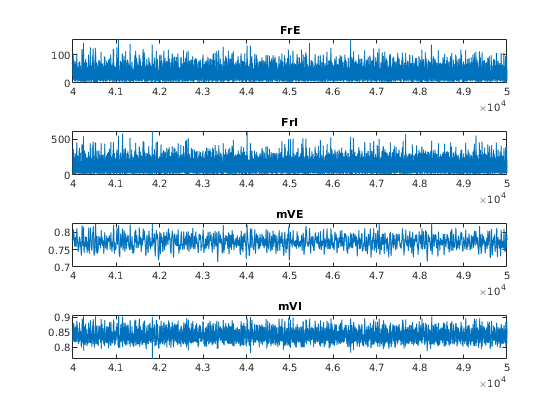

%DataFolder = [pwd '/Figures/Demo042221/'];
TPar = 10;
% read data, and get spike and mV
SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
for TSec = 1:TPar
    text = sprintf('DriveWk_SNW_Sp_TestDly_EE%.1f_IE%.1f_NMDA%d_%d-%d_Fp2.mat',T_EEDly,T_IEDly, tau_nmda_D,...
                                                     TSimOne*(TSec-1),TSimOne*TSec);
    load([DataFolder text],'NWTrace');
    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    for WinInd = 1:length(NWTrace)
    SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
    SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
    mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
    mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];
end
WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
WinSize = StatWin(2) - StatWin(1);

SNWData.VE = nanmean(mVE);
SNWData.VI = nanmean(mVI);
SNWData.SpE = histcounts(SpE(:,2),StatWin);
SNWData.SpI = histcounts(SpI(:,2),StatWin);
clear mVE mVI SpE SpI

Smth = 1;
SNWData.VE = conv(SNWData.VE,1/Smth*ones(1,Smth)); SNWData.VE = SNWData.VE(Smth:end-Smth+1);
SNWData.VI = conv(SNWData.VI,1/Smth*ones(1,Smth)); SNWData.VI = SNWData.VI(Smth:end-Smth+1);
SNWData.SpE = conv(SNWData.SpE,1/Smth*ones(1,Smth)); SNWData.SpE = SNWData.SpE(Smth:end-Smth+1);
SNWData.SpI = conv(SNWData.SpI,1/Smth*ones(1,Smth)); SNWData.SpI = SNWData.SpI(Smth:end-Smth+1);

figure("Name",'Traj on Time')
subplot 411
plot(StatWin(1:end-Smth),SNWData.SpE/N_E/WinSize*1e3)
title('FrE');xlim([4e4 5e4])
subplot 412
plot(StatWin(1:end-Smth),SNWData.SpI/N_I/WinSize*1e3)
title('FrI');xlim([4e4 5e4])
subplot 413
plot(StatWin(1:end-Smth),SNWData.VE)
title('mVE');xlim([4e4 5e4])
subplot 414
plot(StatWin(1:end-Smth),SNWData.VI)
title('mVI');xlim([4e4 5e4])

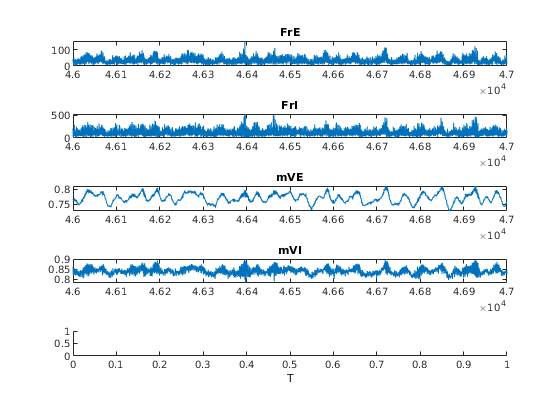


figure("Name",'Raster')
Xrange = [46000 47000];
subplot 511
plot(StatWin(1:end-Smth),SNWData.SpE/N_E/WinSize*1e3)
title('FrE');xlim(Xrange)
subplot 512
plot(StatWin(1:end-Smth),SNWData.SpI/N_I/WinSize*1e3)
title('FrI');xlim(Xrange)
subplot 513
plot(StatWin(1:end-Smth),SNWData.VE)
title('mVE');xlim(Xrange)
subplot 514
plot(StatWin(1:end-Smth),SNWData.VI)
title('mVI');xlim(Xrange)
subplot 515
hold on
%ENeu = floor(N_E/2):N_E; INeu = 1:floor(N_I/2);
% scatter(SpE(:,2), SpE(:,1),0.1 ,'r.')
% scatter(SpI(:,2), SpI(:,1)+max(SpE(:,1)) , 0.1,'b.')
% xlim(Xrange); ylim([floor(N_E*2/3),N_E+floor(N_I/3)])
xlabel('T')

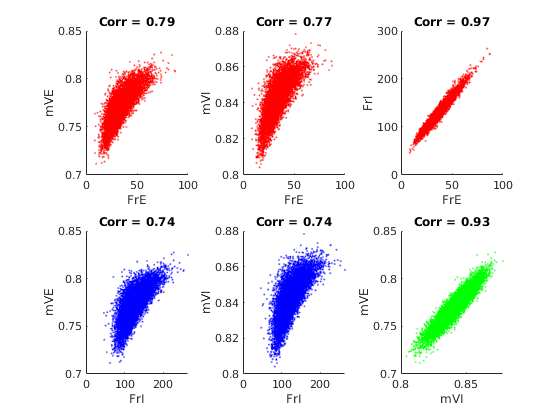


Res = 4; %change bin resolution to 4ms
NewBinSz = floor(Res/WinSize);
Len = length(StatWin)-Smth;
SNWDataRes.SpE = mean(reshape(SNWData.SpE,NewBinSz,floor(Len/NewBinSz)));
SNWDataRes.SpI = mean(reshape(SNWData.SpI,NewBinSz,floor(Len/NewBinSz)));
SNWDataRes.VE = mean(reshape(SNWData.VE,NewBinSz,floor(Len/NewBinSz)));
SNWDataRes.VI = mean(reshape(SNWData.VI,NewBinSz,floor(Len/NewBinSz)));
hCorr = CorrCoefFig(SNWDataRes.SpE/N_E/WinSize*1e3, SNWDataRes.SpI/N_I/WinSize*1e3,...
                    SNWDataRes.VE,                  SNWDataRes.VI);

Spectrogram

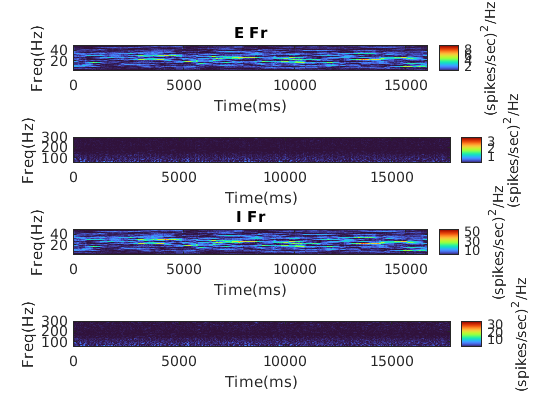

param1.spectrogram_timewindow = 2000;
param1.sdbin = T/WinNum;
param1.frequency_range = [1 50];
param1.duration = [];
param2 = param1; param2.frequency_range = [50,300];
param2.spectrogram_timewindow = 200;
figure('Name','Spectrogram')
subplot 411
spgE1=spectrogram(SNWData.SpE(15e4:24e4)/N_E/WinSize*1e3,param1);
title('E Fr')
subplot 412
spgE2=spectrogram(SNWData.SpE(15e4:24e4)/N_E/WinSize*1e3,param2);

%set(gca,'ColorScale','log')
subplot 413
spgI1=spectrogram(SNWData.SpI(15e4:24e4)/N_I/WinSize*1e3,param1);
title('I Fr')
subplot 414
spgI2=spectrogram(SNWData.SpI(15e4:24e4)/N_I/WinSize*1e3,param2);


%set(gca,'ColorScale','log')
